# Black box moddeling

clear all
clf
syms ss t
s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G=0.1/((s+1)*(s+0.1))

G =
 
         0.1
  -----------------
  s^2 + 1.1 s + 0.1
 
Continuous-time transfer function.



%bode(G)
%step(G)
%pole(G)
G_ss=0.1/((ss+1)*(ss+0.1))

$$G\_ss = \frac{1}{10\,\left(\mathrm{ss}+1\right)\,\left(\mathrm{ss}+\frac{1}{10}\right)}$$

G_t=ilaplace(G_ss*1/ss,ss,t)

$$G\_t = \frac{{\mathrm{e}}^{-t}}{9}-\frac{10\,{\mathrm{e}}^{-\frac{t}{10}}}{9}+1$$

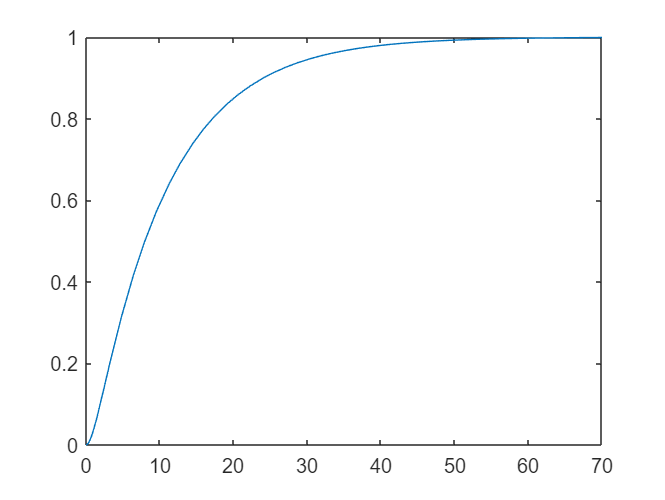

fplot(G_t,[0,70])

G_t(t)=exp(-t)/9 - (10*exp(-t/10))/9 + 1

$$G\_t(t) = \frac{{\mathrm{e}}^{-t}}{9}-\frac{10\,{\mathrm{e}}^{-\frac{t}{10}}}{9}+1$$

t=0:0.2:70

t =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


G_sampled=[zeros(1,50),eval(G_t(t))]'

G_sampled =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


t_2=0:0.2:80

t_2 =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


input=[zeros(1,50),ones(1,length(t))]'

input =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


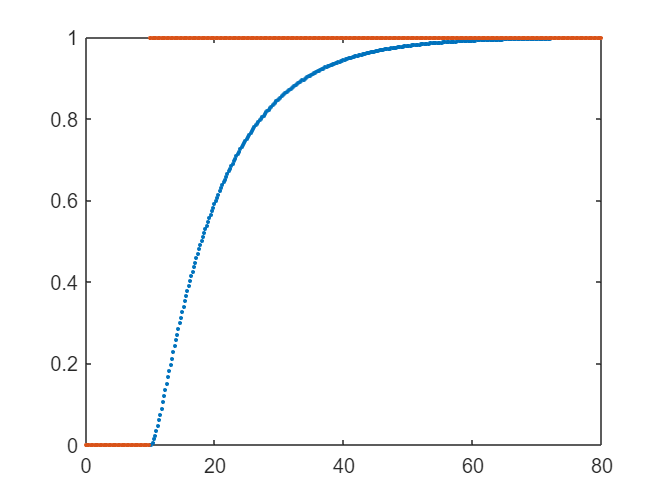

plot(t_2,[G_sampled],'.')
hold on
plot(t_2,[input],'.')


%systemIdentification


## from simulink SISO

clear all
clf
simu=sim("BlackBoxModel.slx",200)

simu =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [220x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


logs=simu.logsout

logs = Simulink.SimulationData.Dataset 'logsout' with 2 elements

                         Name  BlockPath                            
                         ____  ____________________________________ 
    1  [1x1 Signal]      in2   BlackBoxModel/Discrete Transfer Fcn 
    2  [1x1 Signal]      out2  BlackBoxModel/Discrete Transfer Fcn1

  - Use braces { } to access, modify, or add elements using index.


input=logs.getElement(1).Values.Data

input =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


output=logs.getElement(2).Values.Data

output =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


time=logs.getElement(2).Values.Time

time =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


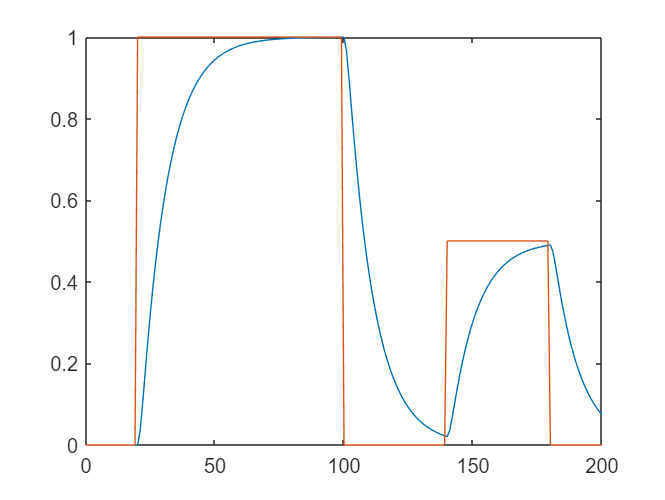

plot(time,output)
hold on
plot(time,input)

## SIMULINK MIMO

clear all
clf
%s80 fra reg 2 bogen
A=[-0.0499,0.0499,0,0;
    0.0499,-0.0667,0,0;
    0,0,-0.0251,0;
    0,0,0.0335,-0.0335].*10

A =    -0.4990    0.4990         0         0
    0.4990   -0.6670         0         0
         0         0   -0.2510         0
         0         0    0.3350   -0.3350


B=[0.00510,0.00510;
    0 0;
    0.0377,-0.0377;
    0,0]

B =     0.0051    0.0051
         0         0
    0.0377   -0.0377
         0         0


C=[1,0,0,0;
    0,0,0,1]

C =      1     0     0     0
     0     0     0     1


sys=ss(A,B,C,0)

sys =
 
  A = 
           x1      x2      x3      x4
   x1  -0.499   0.499       0       0
   x2   0.499  -0.667       0       0
   x3       0       0  -0.251       0
   x4       0       0   0.335  -0.335
 
  B = 
            u1       u2
   x1   0.0051   0.0051
   x2        0        0
   x3   0.0377  -0.0377
   x4        0        0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



tf(sys)

ans =
 
  From input 1 to output...
         0.0051 s + 0.003402
   1:  -----------------------
       s^2 + 1.166 s + 0.08383
 
               0.01263
   2:  -----------------------
       s^2 + 0.586 s + 0.08409
 
  From input 2 to output...
         0.0051 s + 0.003402
   1:  -----------------------
       s^2 + 1.166 s + 0.08383
 
              -0.01263
   2:  -----------------------
       s^2 + 0.586 s + 0.08409
 
Continuous-time transfer function.



eig(A)

ans =    -0.0770
   -1.0890
   -0.3350
   -0.2510


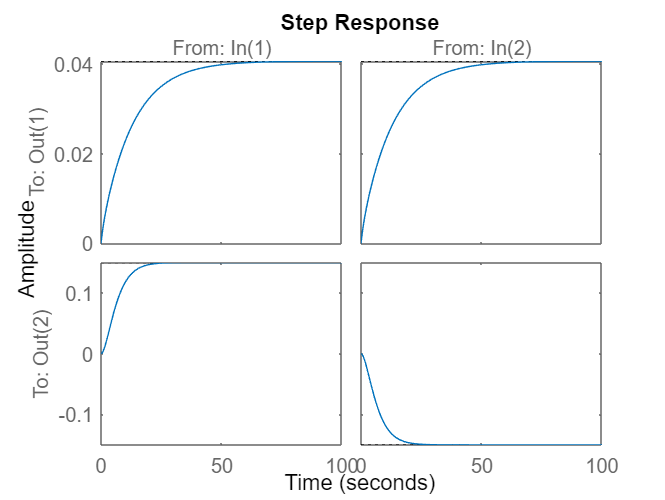

step(sys)


simu=sim("BlackBoxModelMIMO.slx",200)

simu =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [215x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


logs=simu.logsout

logs = Simulink.SimulationData.Dataset 'logsout' with 2 elements

                         Name  BlockPath                                
                         ____  ________________________________________ 
    1  [1x1 Signal]      in2   BlackBoxModelMIMO/Discrete Transfer Fcn 
    2  [1x1 Signal]      out2  BlackBoxModelMIMO/Discrete Transfer Fcn1

  - Use braces { } to access, modify, or add elements using index.


input=logs.getElement(1).Values.Data

input =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


output=logs.getElement(2).Values.Data

output =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


time=logs.getElement(2).Values.Time

time =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


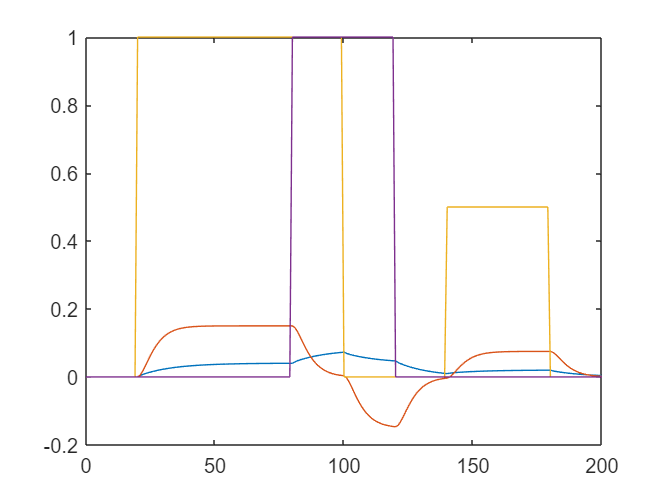

plot(time,output)
hold on
plot(time,input)